%% ===============================================================
%  Plane stress FEM parametric + TWO neural networks predicting full "u" for body forces in x and y direction separately
%  Studying the effect of change in the mesh size
%  - All comments and printed messages are in English
%  - Input normalized to [-1,1], outputs normalized with z-score (per DOF)
%  - Minibatch training using dlnetwork + Adam
%  - Full inference and comparison with FEM
%  Mesh: 6 x 6 nodes (same as requested)
%  Elastic modulus E = 1, nu = 0.3
% ===============================================================

% Global text formatting configuration
set(groot, ...
    'DefaultAxesFontSize', 20, ...     % For ticks, x/y/z labels
    'DefaultTextFontSize', 20, ...     % For manually added text objects
    'DefaultLegendFontSize', 20);      % For graph legends

clear; close all; clc;
%% ===============================================================
% 0️⃣ CREATE AND STORE SAME RANDOM GEOMETRIES FOR ALL MESHES
% ===============================================================

meshList = [4 6 8 12 16];
nMeshes  = length(meshList);

B_min = 1;  B_max = 3;
H_min = 1;  H_max = 3;
nSamples = 2000;

geomFile = 'same_2000_geometries.mat';

if isfile(geomFile)
    load(geomFile, 'Xdata_master', 'B_min', 'B_max', 'H_min', 'H_max', 'nSamples');
    disp('✅ Loaded stored geometry dataset.');
else
    rng(1);   % fixed seed, so results are repeatable

    Xdata_master = zeros(2, nSamples);

    Xdata_master(1,:) = B_min + (B_max - B_min) * rand(1, nSamples);
    Xdata_master(2,:) = H_min + (H_max - H_min) * rand(1, nSamples);

    save(geomFile, 'Xdata_master', 'B_min', 'B_max', 'H_min', 'H_max', 'nSamples');
    disp('✅ Created and saved 1000 random geometries.');
end

✅ Loaded stored geometry dataset.



RMSE_all   = zeros(nMeshes,1);
relL2_all  = zeros(nMeshes,1);
relInf_all = zeros(nMeshes,1);

tic

for m = 1:nMeshes

    nNodesX = meshList(m);
    nNodesY = meshList(m);

    fprintf('🟡 Running mesh %dx%d\n', nNodesX, nNodesY);

    %% ===============================================================
    % 1️⃣  PROBLEM PARAMETERS AND DOMAIN
    % ===============================================================
    nNodes = nNodesX * nNodesY;

    % Material (constant)
    E = 1;
    nu = 0.3;

    % Reference unit mesh
    [xGrid, yGrid] = meshgrid(linspace(0,1,nNodesX), linspace(0,1,nNodesY));
    coords0 = [xGrid(:), yGrid(:)];

    % DOF per node and totals
    ndofNode = 2;
    nDOF = nNodes * ndofNode;

    fprintf('Problem: %d nodes (%dx%d) -> %d DOFs\n', nNodes, nNodesX, nNodesY, nDOF);

    %% ===============================================================
    % 2️⃣  DATASET CREATION (FEM) - body force applied to entire plate
    %     Base (bottom, y==0) is fixed a priori in dataset and training
    % ===============================================================
    % Body force per unit volume (fx, fy)
    bodyForcex = [1; 0];
    bodyForcey = [0; 1];
    % Preallocate outputs
    Xdata = Xdata_master;

    Uall1 = zeros(nDOF, nSamples);
    Uall2 = zeros(nDOF, nSamples);

    fprintf('Generating FEM dataset for mesh %dx%d using same stored geometries...\n', ...
        nNodesX, nNodesY);

    for i = 1:nSamples

        % Same geometry used for every mesh size
        B = Xdata(1,i);
        H = Xdata(2,i);

        % physical coordinates scaled
        coords = [coords0(:,1)*B, coords0(:,2)*H];

        % build FEM stiffness and force
        [K1, F1] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyForcex);
        [K2, F2] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyForcey);

        % identify base nodes
        tol = 1e-12;
        baseNodes = find(abs(coords(:,2)) < tol);

        fixedDOFs = reshape([ ...
            (baseNodes-1)'*ndofNode + 1 ; ...
            (baseNodes-1)'*ndofNode + 2 ], [], 1);

        allDOFs = (1:nDOF)';
        freeDOFs = setdiff(allDOFs, fixedDOFs);

        % Solve x-force case
        u1 = zeros(nDOF,1);
        u1(freeDOFs) = K1(freeDOFs, freeDOFs) \ F1(freeDOFs);

        % Solve y-force case
        u2 = zeros(nDOF,1);
        u2(freeDOFs) = K2(freeDOFs, freeDOFs) \ F2(freeDOFs);

        Uall1(:,i) = u1;
        Uall2(:,i) = u2;

    end
    %
    % Ux_energy = norm(Uall2(1:2:end,:),'fro');
    % Uy_energy = norm(Uall2(2:2:end,:),'fro');
    % fprintf('Energy ratio Uy/Ux = %.3e\n', Uy_energy/Ux_energy);

    disp('✅ FEM dataset generated.');

    %% ===============================================================
    % 3️⃣  DATA PREPARATION AND NORMALIZATION
    %     - Input normalization to [-1,1]
    %     - Output normalization: z-score per DOF
    % ===============================================================
    % Input normalization to [-1,1]
    Bnorm = 2*(Xdata(1,:) - B_min)/(B_max - B_min) - 1;
    Hnorm = 2*(Xdata(2,:) - H_min)/(H_max - H_min) - 1;
    Xnorm = [Bnorm; Hnorm];

    % Output normalization (z-score) per DOF (row-wise)
    epsVal = 1e-8;

    mu_U1 = mean(Uall1,2);
    sigma_U1 = std(Uall1,0,2) + epsVal;
    Uall_norm1 = (Uall1 - mu_U1) ./ sigma_U1;

    mu_U2 = mean(Uall2,2);
    sigma_U2 = std(Uall2,0,2) + epsVal;
    Uall_norm2 = (Uall2 - mu_U2) ./ sigma_U2;

    % Convert to single for speed (optional)
    Xn = single(Xnorm);
    Un1 = single(Uall_norm1);
    Un2 = single(Uall_norm2);

    % Create dlarray for input when needed; minibatches will be formed manually
    dlXall = dlarray(Xn, "CB");

    %% ===============================================================
    % 4️⃣  DEFINE SINGLE NETWORK (mapping 2 -> nDOF)
    % ===============================================================
    % Simple fully-connected network for body force x (NN1)
    nOut = nDOF;
    layers1 = [
        featureInputLayer(2,"Normalization","none") %2 input features;
        fullyConnectedLayer(64)
        % tanhLayer
        reluLayer
        fullyConnectedLayer(64)
        % tanhLayer
        reluLayer
        fullyConnectedLayer(nOut)
        ];
    dlnet1 = dlnetwork(layerGraph(layers1));

    % Simple fully-connected network for body force y (NN2)
    layers2 = [
        featureInputLayer(2,"Normalization","none") %2 input features;
        fullyConnectedLayer(64)
        % tanhLayer
        reluLayer
        fullyConnectedLayer(64)
        % tanhLayer
        reluLayer
        fullyConnectedLayer(nOut)
        ];
    dlnet2 = dlnetwork(layerGraph(layers2));

    %% ===============================================================
    % 5️⃣  TRAINING (minibatch) - manual loop with Adam
    %% ===============================================================
    numEpochs = 1000;
    learnRate = 1e-3;
    miniBatchSize = 200;

    avgGrad1 = [];
    avgSqGrad1 = [];
    avgGrad2 = [];
    avgSqGrad2 = [];

    numIterationsPerEpoch = ceil(nSamples / miniBatchSize);

    disp('🚀 Starting training single network (minibatch Adam)...');

    for epoch = 1:numEpochs
        idx = randperm(nSamples);

        for it = 1:numIterationsPerEpoch
            batchStart = (it-1)*miniBatchSize + 1;
            batchEnd = min(it*miniBatchSize, nSamples);
            batchIdx = idx(batchStart:batchEnd);

            % form minibatch
            Xbatch = dlarray(Xn(:,batchIdx), "CB");
            Ybatch1 = dlarray(Un1(:,batchIdx), "CB");
            Ybatch2 = dlarray(Un2(:,batchIdx), "CB");

            % compute loss and gradients for NN1 & NN2
            [loss1, gradients1] = dlfeval(@modelLoss, dlnet1, Xbatch, Ybatch1);
            [loss2, gradients2] = dlfeval(@modelLoss, dlnet2, Xbatch, Ybatch2);

            % update network parameters for NN1 & NN2 with Adam
            iteration = (epoch-1)*numIterationsPerEpoch + it;
            [dlnet1, avgGrad1, avgSqGrad1] = adamupdate(dlnet1, gradients1, avgGrad1, avgSqGrad1, iteration, learnRate);
            [dlnet2, avgGrad2, avgSqGrad2] = adamupdate(dlnet2, gradients2, avgGrad2, avgSqGrad2, iteration, learnRate);


        end

        if mod(epoch,100)==0 || epoch==1
            fprintf('Epoch %d/%d - Loss (NN1) %.3e ; Loss (NN2) %.3e\n', epoch, numEpochs, gather(extractdata(loss1)),  gather(extractdata(loss2)));
        end

        % optional LR schedule
        if epoch == round(0.7*numEpochs)
            learnRate = learnRate * 0.2;
            fprintf('Learning rate decreased to %.2e at epoch %d\n', learnRate, epoch);
        end
    end

    disp('✅ Training completed.');

    save(['single_net_fullu_', num2str(nNodesX),'x',num2str(nNodesY), '.mat'], ...
        'dlnet1','dlnet2', ...
        'B_min','B_max','H_min','H_max', ...
        'mu_U1','sigma_U1','mu_U2','sigma_U2', ...
        'nNodesX','nNodesY','E','nu','ndofNode');

🟡 Running mesh 4x4


Problem: 16 nodes (4x4) -> 32 DOFs


Generating FEM dataset for mesh 4x4 using same stored geometries...


✅ FEM dataset generated.


🚀 Starting training single network (minibatch Adam)...


Epoch 1/1000 - Loss (NN1) 7.290e-01 ; Loss (NN2) 6.983e-01
Epoch 100/1000 - Loss (NN1) 1.048e-03 ; Loss (NN2) 7.626e-04
Epoch 200/1000 - Loss (NN1) 1.414e-04 ; Loss (NN2) 1.089e-04
Epoch 300/1000 - Loss (NN1) 5.753e-05 ; Loss (NN2) 5.700e-05
Epoch 400/1000 - Loss (NN1) 5.050e-05 ; Loss (NN2) 3.688e-05
Epoch 500/1000 - Loss (NN1) 3.054e-05 ; Loss (NN2) 3.048e-05
Epoch 600/1000 - Loss (NN1) 3.111e-05 ; Loss (NN2) 2.510e-05
Epoch 700/1000 - Loss (NN1) 1.595e-05 ; Loss (NN2) 2.141e-05


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 1.565e-05 ; Loss (NN2) 1.821e-05
Epoch 900/1000 - Loss (NN1) 1.365e-05 ; Loss (NN2) 1.571e-05
Epoch 1000/1000 - Loss (NN1) 1.126e-05 ; Loss (NN2) 1.424e-05


✅ Training completed.


🟡 Running mesh 6x6


Problem: 36 nodes (6x6) -> 72 DOFs


Generating FEM dataset for mesh 6x6 using same stored geometries...


✅ FEM dataset generated.


🚀 Starting training single network (minibatch Adam)...


Epoch 1/1000 - Loss (NN1) 8.890e-01 ; Loss (NN2) 7.740e-01
Epoch 100/1000 - Loss (NN1) 1.263e-03 ; Loss (NN2) 7.969e-04
Epoch 200/1000 - Loss (NN1) 1.808e-04 ; Loss (NN2) 1.463e-04
Epoch 300/1000 - Loss (NN1) 9.451e-05 ; Loss (NN2) 8.889e-05
Epoch 400/1000 - Loss (NN1) 6.656e-05 ; Loss (NN2) 4.713e-05
Epoch 500/1000 - Loss (NN1) 4.245e-05 ; Loss (NN2) 3.373e-05
Epoch 600/1000 - Loss (NN1) 2.287e-05 ; Loss (NN2) 3.183e-05
Epoch 700/1000 - Loss (NN1) 1.712e-05 ; Loss (NN2) 2.219e-05


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 1.698e-05 ; Loss (NN2) 1.802e-05
Epoch 900/1000 - Loss (NN1) 1.250e-05 ; Loss (NN2) 1.528e-05
Epoch 1000/1000 - Loss (NN1) 1.268e-05 ; Loss (NN2) 1.429e-05


✅ Training completed.


🟡 Running mesh 8x8


Problem: 64 nodes (8x8) -> 128 DOFs


Generating FEM dataset for mesh 8x8 using same stored geometries...


✅ FEM dataset generated.


🚀 Starting training single network (minibatch Adam)...


Epoch 1/1000 - Loss (NN1) 7.646e-01 ; Loss (NN2) 7.914e-01
Epoch 100/1000 - Loss (NN1) 4.278e-04 ; Loss (NN2) 6.460e-04
Epoch 200/1000 - Loss (NN1) 1.383e-04 ; Loss (NN2) 1.943e-04
Epoch 300/1000 - Loss (NN1) 1.049e-04 ; Loss (NN2) 1.081e-04
Epoch 400/1000 - Loss (NN1) 6.834e-05 ; Loss (NN2) 5.761e-05
Epoch 500/1000 - Loss (NN1) 3.365e-05 ; Loss (NN2) 4.328e-05
Epoch 600/1000 - Loss (NN1) 3.279e-05 ; Loss (NN2) 2.759e-05
Epoch 700/1000 - Loss (NN1) 2.281e-05 ; Loss (NN2) 2.734e-05


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 1.383e-05 ; Loss (NN2) 1.806e-05
Epoch 900/1000 - Loss (NN1) 1.287e-05 ; Loss (NN2) 1.713e-05
Epoch 1000/1000 - Loss (NN1) 1.151e-05 ; Loss (NN2) 1.634e-05


✅ Training completed.


🟡 Running mesh 12x12


Problem: 144 nodes (12x12) -> 288 DOFs


Generating FEM dataset for mesh 12x12 using same stored geometries...


✅ FEM dataset generated.


🚀 Starting training single network (minibatch Adam)...


Epoch 1/1000 - Loss (NN1) 7.105e-01 ; Loss (NN2) 8.862e-01
Epoch 100/1000 - Loss (NN1) 3.524e-04 ; Loss (NN2) 6.366e-04
Epoch 200/1000 - Loss (NN1) 1.126e-04 ; Loss (NN2) 1.528e-04
Epoch 300/1000 - Loss (NN1) 4.623e-05 ; Loss (NN2) 6.128e-05
Epoch 400/1000 - Loss (NN1) 3.083e-05 ; Loss (NN2) 4.204e-05
Epoch 500/1000 - Loss (NN1) 2.699e-05 ; Loss (NN2) 2.995e-05
Epoch 600/1000 - Loss (NN1) 3.282e-05 ; Loss (NN2) 2.763e-05
Epoch 700/1000 - Loss (NN1) 1.764e-05 ; Loss (NN2) 2.539e-05


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 1.150e-05 ; Loss (NN2) 1.616e-05
Epoch 900/1000 - Loss (NN1) 1.062e-05 ; Loss (NN2) 1.562e-05
Epoch 1000/1000 - Loss (NN1) 8.452e-06 ; Loss (NN2) 1.664e-05


✅ Training completed.


🟡 Running mesh 16x16


Problem: 256 nodes (16x16) -> 512 DOFs


Generating FEM dataset for mesh 16x16 using same stored geometries...


✅ FEM dataset generated.


🚀 Starting training single network (minibatch Adam)...


Epoch 1/1000 - Loss (NN1) 1.053e+00 ; Loss (NN2) 9.546e-01
Epoch 100/1000 - Loss (NN1) 4.703e-04 ; Loss (NN2) 5.915e-04
Epoch 200/1000 - Loss (NN1) 8.640e-05 ; Loss (NN2) 1.131e-04
Epoch 300/1000 - Loss (NN1) 6.415e-05 ; Loss (NN2) 5.518e-05
Epoch 400/1000 - Loss (NN1) 3.374e-05 ; Loss (NN2) 5.383e-05
Epoch 500/1000 - Loss (NN1) 3.161e-05 ; Loss (NN2) 4.677e-05
Epoch 600/1000 - Loss (NN1) 8.073e-05 ; Loss (NN2) 2.618e-05
Epoch 700/1000 - Loss (NN1) 1.436e-05 ; Loss (NN2) 2.392e-05


Learning rate decreased to 2.00e-04 at epoch 700


Epoch 800/1000 - Loss (NN1) 1.216e-05 ; Loss (NN2) 1.538e-05
Epoch 900/1000 - Loss (NN1) 1.429e-05 ; Loss (NN2) 1.546e-05
Epoch 1000/1000 - Loss (NN1) 7.349e-06 ; Loss (NN2) 1.329e-05


✅ Training completed.



    %% ===============================================================
    %  INFERENCE + COMPARISON WITH FEM
    %  (we predict full u from the single network, then de-normalize)
    % ===============================================================

    %change these 4 parameters for testing
    Btest = 1.25;
    Htest = 2.0;
    bodyforcetestx = [2;0];
    bodyforcetesty = [0;3];

    % --- Normalize geometry input ---
    Bnorm_t = 2*(Btest - B_min)/(B_max - B_min) - 1;
    Hnorm_t = 2*(Htest - H_min)/(H_max - H_min) - 1;
    dlGeom = dlarray(single([Bnorm_t; Hnorm_t]), "CB");

    % --- Predict normalized u for body force x & y (NN1 & NN2) ---
    u_norm_dl1 = predict(dlnet1, dlGeom);
    u_norm1 = double(extractdata(u_norm_dl1));
    u_norm_dl2 = predict(dlnet2, dlGeom);
    u_norm2 = double(extractdata(u_norm_dl2));

    % --- De-normalize to physical scale ---
    u_pred1 = (u_norm1 .* mu_U1*0 + 0);
    u_pred1 = (u_norm1 .* sigma_U1) + mu_U1;
    u_pred1 = u_pred1 .* bodyforcetestx(1);
    % u_pred1 = u_pred1 .* 1;

    u_pred2 = (u_norm2 .* mu_U2*0 + 0);
    u_pred2 = (u_norm2 .* sigma_U2) + mu_U2;
    u_pred2 = u_pred2 .* bodyforcetesty(2);
    % u_pred2 = u_pred2 .* 1;

    % --- FEM solution for the same geometry (base fixed) ---
    coords = [coords0(:,1)*Btest, coords0(:,2)*Htest];
    [K1, F1] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyforcetestx);
    [K2, F2] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyforcetesty);

    % apply base fixed BC (y==0)
    tol = 1e-12;
    baseNodes = find(abs(coords(:,2) - 0) < tol);
    fixedDOFs = reshape([ (baseNodes-1)'*ndofNode + 1 ; (baseNodes-1)'*ndofNode + 2 ], [], 1);
    allDOFs = (1:nDOF)';
    freeDOFs = setdiff(allDOFs, fixedDOFs);

    u_fem1 = zeros(nDOF,1);
    u_fem2 = zeros(nDOF,1);

    u_fem1(freeDOFs) = K1(freeDOFs, freeDOFs) \ F1(freeDOFs);
    u_fem2(freeDOFs) = K2(freeDOFs, freeDOFs) \ F2(freeDOFs);

    % --- Compare FEM vs NN ---
    u_NN1= u_pred1(:);
    u_FEM1 = u_fem1(:);
    u_NN2 = u_pred2(:);
    u_FEM2 = u_fem2(:);

    % extract u_x and u_y components
    u_x_FEM1 = u_FEM1(1:2:end);
    u_y_FEM1 = u_FEM1(2:2:end);
    u_x_NN1  = u_NN1(1:2:end);
    u_y_NN1  = u_NN1(2:2:end);

    u_x_FEM2 = u_FEM2(1:2:end);
    u_y_FEM2 = u_FEM2(2:2:end);
    u_x_NN2  = u_NN2(1:2:end);
    u_y_NN2  = u_NN2(2:2:end);

    % reshape on grid
    Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
    Ycoords = reshape(coords(:,2), nNodesY, nNodesX);

    UxF1 = reshape(u_x_FEM1, nNodesY, nNodesX);
    UyF1 = reshape(u_y_FEM1, nNodesY, nNodesX);
    UxN1 = reshape(u_x_NN1,  nNodesY, nNodesX);
    UyN1 = reshape(u_y_NN1,  nNodesY, nNodesX);

    UxF2 = reshape(u_x_FEM2, nNodesY, nNodesX);
    UyF2 = reshape(u_y_FEM2, nNodesY, nNodesX);
    UxN2 = reshape(u_x_NN2,  nNodesY, nNodesX);
    UyN2 = reshape(u_y_NN2,  nNodesY, nNodesX);

    UxF = UxF1 + UxF2;
    UyF = UyF1 + UyF2;
    UxN = UxN1 + UxN2;
    UyN = UyN1 + UyN2;

    %error
    Err_u = abs(UxF - UxN);
    Err_v = abs(UyF - UyN);
    % Err_u1 = abs(UxF1 - UxN1);
    % Err_v1 = abs(UyF1 - UyN1);
    % Err_u2 = abs(UxF2 - UxN2);
    % Err_v2 = abs(UyF2 - UyN2);
    %
    % %figures for NN1
    % fprintf('Figures for NN1 (body force x = %d):', bodyforcetestx(1));
    % figure('Position',[100 100 1400 800]);
    %
    % subplot(2,3,1);
    % pcolor(Xcoords, Ycoords, UxF1); shading interp; colorbar; axis equal tight;
    % title('FEM1 - u_x');
    %
    % subplot(2,3,2);
    % pcolor(Xcoords, Ycoords, UxN1); shading interp; colorbar; axis equal tight;
    % title('NN1 - u_x');
    %
    % subplot(2,3,3);
    % pcolor(Xcoords, Ycoords, abs(UxF1 - UxN1)); shading interp; colorbar; axis equal tight;
    % title('|u_x^{FEM1} - u_x^{NN1}|');
    %
    % subplot(2,3,4);
    % pcolor(Xcoords, Ycoords, UyF1); shading interp; colorbar; axis equal tight;
    % title('FEM1 - u_y');
    %
    % subplot(2,3,5);
    % pcolor(Xcoords, Ycoords, UyN1); shading interp; colorbar; axis equal tight;
    % title('NN1 - u_y');
    %
    % subplot(2,3,6);
    % pcolor(Xcoords, Ycoords, abs(UyF1 - UyN1)); shading interp; colorbar; axis equal tight;
    % title('|u_y^{FEM1} - u_y^{NN1}|');
    %
    %
    % %figures for NN2
    % fprintf('Figures for NN2 (body force y = %d):', bodyforcetesty(2))
    % figure('Position',[100 100 1400 800]);
    %
    % subplot(2,3,1);
    % pcolor(Xcoords, Ycoords, UxF2); shading interp; colorbar; axis equal tight;
    % title('FEM2 - u_x');
    %
    % subplot(2,3,2);
    % pcolor(Xcoords, Ycoords, UxN2); shading interp; colorbar; axis equal tight;
    % title('NN2 - u_x');
    %
    % subplot(2,3,3);
    % pcolor(Xcoords, Ycoords, abs(UxF2 - UxN2)); shading interp; colorbar; axis equal tight;
    % title('|u_x^{FEM2} - u_x^{NN2}|');
    %
    % subplot(2,3,4);
    % pcolor(Xcoords, Ycoords, UyF2); shading interp; colorbar; axis equal tight;
    % title('FEM2 - u_y');
    %
    % subplot(2,3,5);
    % pcolor(Xcoords, Ycoords, UyN2); shading interp; colorbar; axis equal tight;
    % title('NN2 - u_y');
    %
    % subplot(2,3,6);
    % pcolor(Xcoords, Ycoords, abs(UyF2 - UyN2)); shading interp; colorbar; axis equal tight;
    % title('|u_y^{FEM2} - u_y^{NN2}|');
    %
    %
    % %figures
    % disp('Figures for combined displacements:')
    % figure('Position',[100 100 1400 800]);
    %
    % subplot(2,3,1);
    % pcolor(Xcoords, Ycoords, UxF); shading interp; colorbar; axis equal tight;
    % title('FEM - u_x');
    %
    % subplot(2,3,2);
    % pcolor(Xcoords, Ycoords, UxN); shading interp; colorbar; axis equal tight;
    % title('NN - u_x');
    %
    % subplot(2,3,3);
    % pcolor(Xcoords, Ycoords, Err_u); shading interp; colorbar; axis equal tight;
    % title('|u_x^{FEM} - u_x^{NN}|');
    %
    % subplot(2,3,4);
    % pcolor(Xcoords, Ycoords, UyF); shading interp; colorbar; axis equal tight;
    % title('FEM - u_y');
    %
    % subplot(2,3,5);
    % pcolor(Xcoords, Ycoords, UyN); shading interp; colorbar; axis equal tight;
    % title('NN - u_y');
    %
    % subplot(2,3,6);
    % pcolor(Xcoords, Ycoords, Err_v); shading interp; colorbar; axis equal tight;
    % title('|u_y^{FEM} - u_y^{NN}|');

    % Errors
    u_FEM = u_FEM1 + u_FEM2;
    u_NN  = u_NN1  + u_NN2;

    err_vec = u_FEM - u_NN;
    e = err_vec;
    u_ref = u_FEM;

    RMSE   = norm(e) / sqrt(numel(e));
    relL2  = norm(e) / norm(u_ref);
    maxErr = norm(e, Inf) / norm(u_ref, Inf);

    fprintf('RMSE   : %.3e\n', RMSE);
    fprintf('Relative L2 error : %.3e\n', relL2);
    fprintf('Relative Infinity norm error: %.3e\n', maxErr);
    disp('✅ Verification completed.');

    RMSE_all(m)   = RMSE;
    relL2_all(m)  = relL2;
    relInf_all(m) = maxErr;

end

RMSE   : 5.735e-02


Relative L2 error : 3.091e-03


Relative Infinity norm error: 4.916e-03


✅ Verification completed.


RMSE   : 7.554e-02


Relative L2 error : 4.118e-03


Relative Infinity norm error: 7.890e-03


✅ Verification completed.


RMSE   : 4.199e-02


Relative L2 error : 2.305e-03


Relative Infinity norm error: 3.391e-03


✅ Verification completed.


RMSE   : 4.169e-02


Relative L2 error : 2.308e-03


Relative Infinity norm error: 5.904e-03


✅ Verification completed.


RMSE   : 4.942e-02


Relative L2 error : 2.749e-03


Relative Infinity norm error: 6.549e-03


✅ Verification completed.


disp("Time for data generation, training and inference:")

Time for data generation, training and inference:


toc

Elapsed time is 838.845576 seconds.


Plots

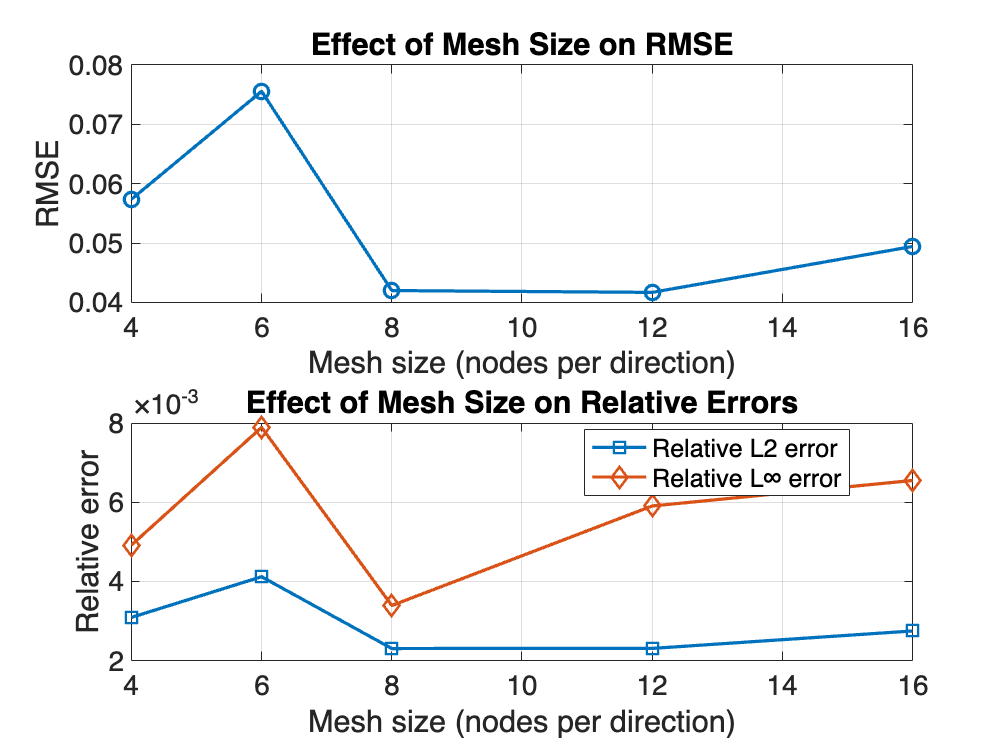

set(groot, ...
    'DefaultAxesFontSize', 17, ...     % For ticks, x/y/z labels
    'DefaultTextFontSize', 20, ...     % For manually added text objects
    'DefaultLegendFontSize', 20);      % For graph legends

% figure;
% plot(meshList, RMSE_all, '-o','LineWidth',1.5); hold on;
% plot(meshList, relL2_all, '-s','LineWidth',1.5);
% plot(meshList, relInf_all, '-d','LineWidth',1.5);
% grid on;
% 
% xlabel('Mesh (Number of nodes per direction)');
% ylabel('Error');
% legend('RMSE','Relative L2','Relative L∞');
% title('Effect of Mesh Size');

%% ---------------------------------------------------------------
% Figure 1: RMSE only
% ---------------------------------------------------------------
figure;
subplot(2,1,1)
plot(meshList, RMSE_all, '-o', 'LineWidth', 1.8, 'MarkerSize', 8);
grid on;

xlabel('Mesh size (nodes per direction)');
ylabel('RMSE');
title('Effect of Mesh Size on RMSE');

%% ---------------------------------------------------------------
% Figure 2: Relative errors only
% ---------------------------------------------------------------
subplot(2,1,2)
plot(meshList, relL2_all, '-s', 'LineWidth', 1.8, 'MarkerSize', 8); 
hold on;
plot(meshList, relInf_all, '-d', 'LineWidth', 1.8, 'MarkerSize', 8);
grid on;

xlabel('Mesh size (nodes per direction)');
ylabel('Relative error');
legend('Relative L2 error', 'Relative L∞ error', 'Location', 'best');
title('Effect of Mesh Size on Relative Errors');

===============================================================

Local functions

===============================================================


function [K,F] = buildPlaneStressFEM(coords,nx,ny,E,nu,bodyForce)
% Structured mesh of 4-node bilinear quadrilateral elements
nNodes = nx*ny;
nElemX = nx-1; nElemY = ny-1;
nElem = nElemX * nElemY;
ndofNode = 2;
nDOF = nNodes * ndofNode; %total dof of system

% element connectivity matrix
%(ix, iy) is one quadrilateral element
conn = zeros(nElem,4);
for ix = 1:nElemX
    for jy = 1:nElemY
        n1 = (ix-1)*ny + jy;
        n2 = ix*ny + jy;
        n3 = ix*ny + (jy+1);
        n4 = (ix-1)*ny + (jy+1);
        e = (ix-1)*nElemY + jy; %This converts the 2D element index (ix, jy) into a single element number
        conn(e,:) = [n1 n2 n3 n4]; %Element e connects nodes n1, n2, n3, n4
    end
end

K = zeros(nDOF);
F = zeros(nDOF,1);

% Plane stress constitutive matrix
D = E / (1 - nu^2) * [1, nu, 0;
    nu, 1, 0;
    0, 0, (1-nu)/2];

% 2x2 Gauss
gp = [-1/sqrt(3), 1/sqrt(3)];
wgp = [1,1];

for e = 1:nElem
    nodes = conn(e,:);
    xe = coords(nodes,1);
    ye = coords(nodes,2);

    %element stiffness and force matrix
    Ke = zeros(8,8);
    Fe = zeros(8,1);

    % Reduced integration term B0 for shear (as in original)
    xi = 0; eta = 0;
    [N0, dNdxi0, dNdeta0] = shape4(xi,eta);
    J0 = [dNdxi0'; dNdeta0'] * [xe, ye];
    detJ0 = det(J0);
    invJ0 = inv(J0);
    dN0 = [dNdxi0, dNdeta0] * invJ0;

    B0 = zeros(3,8);
    for a = 1:4
        dNx = dN0(a,1);
        dNy = dN0(a,2);
        col = (a-1)*2;
        B0(1, col + 1) = dNx;
        B0(2, col + 2) = dNy;
        B0(3, col + 1) = dNy;
        B0(3, col + 2) = dNx;
    end

    for i = 1:2
        for j = 1:2
            xi = gp(i); eta = gp(j);
            [N, dNdxi, dNdeta] = shape4(xi,eta);
            J = [dNdxi'; dNdeta'] * [xe, ye];
            detJ = det(J);
            invJ = inv(J);
            dN = [dNdxi, dNdeta] * invJ;

            B = zeros(3,8);
            for a = 1:4
                dNx = dN(a,1);
                dNy = dN(a,2);
                col = (a-1)*2;
                B(1, col + 1) = dNx;
                B(2, col + 2) = dNy;
                B(3, col + 1) = dNy;
                B(3, col + 2) = dNx;
            end

            % replace shear row with reduced B0 shear row
            B(3,:) = B0(3,:);

            Ke = Ke + (B' * D * B) * detJ * wgp(i) * wgp(j);

            Nmat = zeros(2,8);
            for a = 1:4
                Nmat(1, (a-1)*2 + 1) = N(a);
                Nmat(2, (a-1)*2 + 2) = N(a);
            end
            Fe = Fe + (Nmat' * bodyForce) * detJ * wgp(i) * wgp(j);
        end
    end

    % assemble
    gdofs = zeros(8,1);
    for a = 1:4
        node = nodes(a);
        gdofs((a-1)*2 + (1:2)) = (node-1)*2 + (1:2);
    end
    K(gdofs, gdofs) = K(gdofs, gdofs) + Ke;
    F(gdofs) = F(gdofs) + Fe;
end
end

function [N, dNdxi, dNdeta] = shape4(xi,eta)
N = 0.25*[(1-xi)*(1-eta);
    (1+xi)*(1-eta);
    (1+xi)*(1+eta);
    (1-xi)*(1+eta)];
dNdxi  = 0.25*[-(1-eta); (1-eta); (1+eta); -(1+eta)];
dNdeta = 0.25*[-(1-xi); -(1+xi); (1+xi);  (1-xi)];
end

function [loss,gradients] = modelLoss(dlnet,X,Y)
% Simple MSE loss for single network
Ypred = forward(dlnet,X);
loss = mean((Ypred - Y).^2,'all');
gradients = dlgradient(loss, dlnet.Learnables);
end


